clc; close all; clear all;

s = tf('s');
P2 = (3)/(0.2*s+1)/((3*s+1)*(s+1));
C2 = pidtune(P2,'PID')

C2 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.642, Ki = 0.227, Kd = 0.394
 
Continuous-time PID controller in parallel form.
Model Properties



Plc1 = feedback(P2*C2,1)

Plc1 =
 
            1.182 s^2 + 1.926 s + 0.6818
  ------------------------------------------------
  0.6 s^4 + 3.8 s^3 + 5.382 s^2 + 2.926 s + 0.6818
 
Continuous-time transfer function.
Model Properties


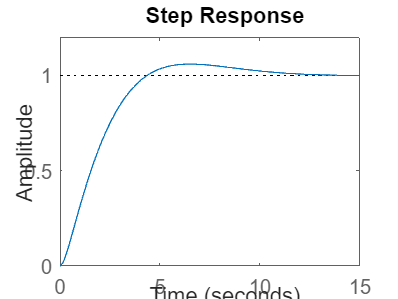

step(Plc1)


P1 = 0.8/((4*s+1)*(s+1))

P1 =
 
        0.8
  ---------------
  4 s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties



POL = Plc1*P1;
C1 = pidtune(POL,'PID')

C1 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 2.54, Ki = 0.488, Kd = 3.22
 
Continuous-time PID controller in parallel form.
Model Properties


Plc2 = feedback(POL*C1,1)

Plc2 =
 
                  3.043 s^4 + 7.363 s^3 + 6.136 s^2 + 2.14 s + 0.2663
  ------------------------------------------------------------------------------------
  2.4 s^7 + 18.2 s^6 + 41.13 s^5 + 45.46 s^4 + 30.1 s^3 + 12.47 s^2 + 2.821 s + 0.2663
 
Continuous-time transfer function.
Model Properties


pole(Plc2)

ans =   -4.6689 + 0.0000i
  -1.0644 + 0.0000i
  -0.7708 + 0.0000i
  -0.2705 + 0.5325i
  -0.2705 - 0.5325i
  -0.2691 + 0.0939i
  -0.2691 - 0.0939i


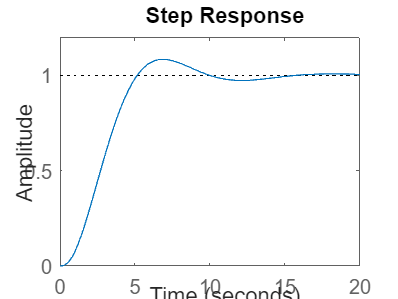

step(Plc2)

%Control de TORQUE  ----> PID / PID
clc, close all; clear all;

s = tf('s');
Km = 0.01;
J = 0.01;
b = 0.1;
Lm = 0.5;
Rm = 1;

A = [-b/J Km/J; -Km/Lm -Rm/Lm];
B = [0; 1/Lm];
C = [-b Km];
D = [0];
Gss = ss(A,B,C,D);
P2 = tf(Gss);
C2 = pidtune(P2,'PID')

C2 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.24e+03, Ki = 5.89e+04, Kd = 6.06
 
Continuous-time PID controller in parallel form.
Model Properties


Plc1 = feedback(P2*C2,1)

Plc1 =
 
  0.1212 s^3 + 24.84 s^2 + 1178 s - 2.96e-12
  ------------------------------------------
  1.121 s^3 + 36.84 s^2 + 1198 s - 2.96e-12
 
Continuous-time transfer function.
Model Properties


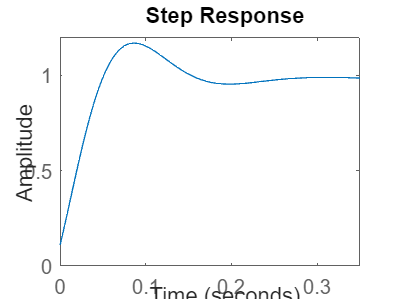

step(Plc1)


P1 = 1/(J*s^2)

P1 =
 
     1
  --------
  0.01 s^2
 
Continuous-time transfer function.
Model Properties



POL = P1*Plc1;
C1 = pidtune(POL,'PID')

C1 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.154, Ki = 0.031, Kd = 0.191
 
Continuous-time PID controller in parallel form.
Model Properties


Plc2 = feedback(POL*C1,1)

Plc2 =
 
        0.02318 s^5 + 4.768 s^4 + 229.1 s^3 + 182.1 s^2 + 36.5 s - 9.17e-14
  --------------------------------------------------------------------------------
  0.01121 s^6 + 0.3916 s^5 + 16.75 s^4 + 229.1 s^3 + 182.1 s^2 + 36.5 s - 9.17e-14
 
Continuous-time transfer function.
Model Properties


pole(Plc2)

ans =   -8.8738 +33.1148i
  -8.8738 -33.1148i
 -16.3423 + 0.0000i
  -0.4788 + 0.0000i
  -0.3540 + 0.0000i
   0.0000 + 0.0000i


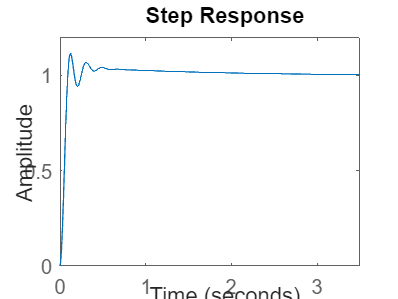

step(Plc2)

%Control de Corriente  ----> PID/PID
clc, close all; clear all;

s = tf('s');
Km = 0.01;
J = 0.01;
b = 0.1;
Lm = 0.5;
Rm = 1;

A = [-b/J Km/J; -Km/Lm -Rm/Lm];
B = [0; 1/Lm];
C = [0 1];
D = [0];
Gss = ss(A,B,C,D);
P2 = tf(Gss);
C2 = pidtune(P2,'PID')

C2 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.42, Ki = 5.17
 
Continuous-time PI controller in parallel form.
Model Properties


Plc1 = feedback(P2*C2,1)

Plc1 =
 
     2.85 s^2 + 38.83 s + 103.3
  ---------------------------------
  s^3 + 14.85 s^2 + 58.85 s + 103.3
 
Continuous-time transfer function.
Model Properties


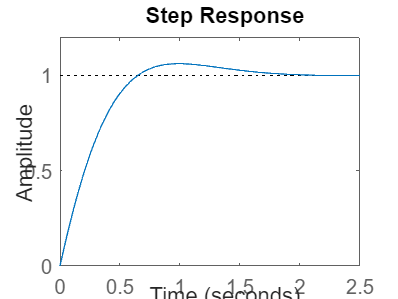

step(Plc1)


P1 = Km/(J*s^2+b*s)

P1 =
 
        0.01
  ----------------
  0.01 s^2 + 0.1 s
 
Continuous-time transfer function.
Model Properties



POL = P1*Plc1;
C1 = pidtune(POL,'PID')

C1 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 39.7, Ki = 19.3, Kd = 20.4
 
Continuous-time PID controller in parallel form.
Model Properties


Plc2 = feedback(POL*C1,1)

Plc2 =
 
             0.5825 s^4 + 9.069 s^3 + 37.08 s^2 + 48.51 s + 19.92
  ---------------------------------------------------------------------------
  0.01 s^6 + 0.2485 s^5 + 2.656 s^4 + 15.99 s^3 + 47.41 s^2 + 48.51 s + 19.92
 
Continuous-time transfer function.
Model Properties


pole(Plc2)

ans =  -10.0000 + 0.0000i
  -4.1613 + 6.1264i
  -4.1613 - 6.1264i
  -5.1159 + 0.0000i
  -0.7056 + 0.4605i
  -0.7056 - 0.4605i


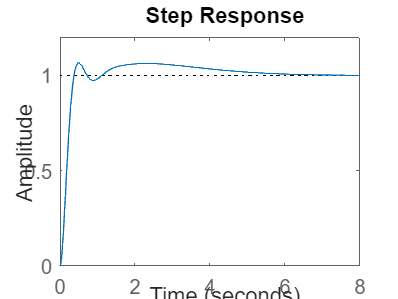

step(Plc2)

%Control de Corriente ----> LQR/LQG
clc, close all; clear all;
clc;clear all;close all;
s=tf('s')
Km=0.01;
J=0.01;
b=0.1;
Lm=0.5;
Rm=1;
A=[-b/J Km/J;-Km/Lm -Rm/Lm];
B=[0;1/Lm];
C=[1 0];
D=[0];

Q=diag([1000 1]);
R=0.01;
K=lqr(A,B,Q,R)
Kr=(-(C-D*K)*(A-B*K)^-1*B+D)^-1

ACL=A-B*K;
BCL=B*Kr;
CCL=C-D*K;
DCL=D*Kr;
GCL2=ss(ACL,BCL,CCL,DCL)
step(GCL2)

%% Pregunta c caso 1: solo encoder de posicion
%1er paso LQR 

GOL1=1/s*GCL2

A1=GOL1.A
B1=GOL1.B
C1=GOL1.C
D1=GOL1.D

Qy=1;
Q1=C1'*Qy*C1;
R1=0.001;
K1=lqr(A1,B1,Q1,R1)
Kr1=(-(C1-D1*K1)*(A1-B1*K1)^-1*B1+D1)^-1;
%2do paso L lq
G1=eye(3)
Qw=0.01*diag([1 1 1]);
Vv=0.0001;
L1=lqe(A1,G1,C1,Qw,Vv)
%3er paso ss
ACL2=[A1 -B1*K1;L1*C1 A1-B1*K1-L1*C1]
BCL2=[B1*Kr1;B1*Kr1];
CCL2=[C1 -D1*K1];
DCL2=[D1*Kr1];
GCL2=ss(ACL2,BCL2,CCL2,DCL2);
step(GCL2)
